# AFC RL Training

clear;
close all;
bdclose('all');
% addpath("/Users/jiayangsong/Documents/git/AI-CPS-Ensemble/AFC/model");
addpath("/home/momentumlab/Documents/git/AI-CPS-Ensemble/AFC/model");

## Environment Setup

Ts = 0.1;               % sample time for execution
T = 30;                 % simulation duration in sec
Ts_sample = Ts;         % sample time for data extraction
fuel_inj_tol=1.0;
MAF_sensor_tol=1.0;     % MAF sensor error factor
AF_sensor_tol=1.0; 
pump_tol=1.0;
kappa_tol=1.0;
tau_ww_tol=1.0;
fault_time=50;
kp=0.04;
ki=0.14;

fuel_inj_max = 1.66;    % max/min controller output (fuel injection)
fuel_inj_min = 0.13;

%The engine speed is constrained to the range [900,1100].
min_Engine_Speed = 900;
max_Engine_Speed = 1100;

%The pedal angle is constrained to the range [8.8,61.1].
min_Pedal_Angle = 1;
max_Pedal_Angle = 52;

change_freq_PA = 4;         % input signal change value every 3 sec
change_freq_ES = 2;

power_threshold = 70;       % pedal angle threshold for power mode
max_mu_normal = 0.02;       % max mu for normal mode
max_mu_power = 0.2;         % max mu for power mode
steady_mu = 0.02;           % max mu for steady state in normal mode
edge_mu = 0.05;             % max mu for rising/falling edge in normal mode
AF_ref_normal = 14.7;       % ref A/F for normal mode
AF_ref_power = 12.5;        % ref A/F for power mode
mu_tol_normal = 0.3;        % mu value to terminate the episode
time_tol = 10;               % time tolerence, to avoid the initial large mu value

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- Engine Spped

- Pedal Angle

- Throttle Flow

- Air by Fuel mass

- AF ratio error (mu)

**Action**: Ego car acceleration

% observation
obsInfo = rlNumericSpec([5 1],...
    'LowerLimit', -inf*ones(5,1),...
    'UpperLimit', inf*ones(5,1));
obIsnfo.Name = 'observation';
obsInfo.Description = 'ES, PA, flow, AF_mass, mu';
numObservations = obsInfo.Dimension(1);

% action
actInfo = rlNumericSpec([1 1]);
actInfo.LowerLimit = 0.45;
actInfo.UpperLimit = 0.58;
actInfo.Name = 'commanded_fuel';
numActions = actInfo.Dimension(1);

mdl = 'AFC_RL_training';
agentblk = [mdl, '/Air Fuel Control Model/RL Agent'];

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

% Set a custom reset function that randomizes the reference values for the model.
% env.ResetFcn = @(in)localResetFcn(in);

% Fix the random generator seed for reproducibility
% rng(0);

## DRL Agent Configuration

[https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagent.html](https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagent.html)

**Create a network to be used as underlying critic approximator**

[https://www.mathworks.com/help/reinforcement-learning/ref/rlqvaluefunction.html#mw_7ca25508-5448-42fe-bb4e-61d437328c47](https://www.mathworks.com/help/reinforcement-learning/ref/rlqvaluefunction.html#mw_7ca25508-5448-42fe-bb4e-61d437328c47)

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(16,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(128,'Name','CriticStateFC2')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(16,'Name','CriticActionFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(128,'Name','CriticActionFC2')];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(265,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(128,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(16,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC2','add/in2');

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);
% create 1st critics based on the network approximator
critic1 = rlQValueFunction(criticNetwork,obsInfo,actInfo,'UseDevice','cpu');

Second Critic with different NN structure

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(16,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(16,'Name','CriticActionFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(64,'Name','CriticActionFC2')];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(128,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(16,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC2','add/in2');

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create 2nd critics based on the network approximator
critic2 = rlQValueFunction(criticNetwork,obsInfo,actInfo,'UseDevice','cpu');

**Create a network to be used as underlying actor approximator**

[https://www.mathworks.com/help/reinforcement-learning/ref/rltd3agent.html](https://www.mathworks.com/help/reinforcement-learning/ref/rltd3agent.html)

actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(16,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(32,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(64,'Name','ActorFC3')
    reluLayer('Name','ActorRelu3')
    fullyConnectedLayer(32,'Name','ActorFC4')
    reluLayer('Name','ActorRelu4')
    fullyConnectedLayer(16,'Name','ActorFC5')
    reluLayer('Name','ActorRelu5')
    fullyConnectedLayer(1,'Name','ActorFC6')
    ];
% tanhLayer('Name','ActorTanh1')
% scalingLayer('Name','action','Scale',0.765, 'Bias',0.895)

actor  = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

**DRL agent options**

[https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagentoptions.html](https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagentoptions.html)

% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

% Options for SAC agent
agentOptions = rlTD3AgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'TargetUpdateFrequency',1,...
    'ExperienceBufferLength',1e4,...
    'NumStepsToLookAhead',10,...
    'MiniBatchSize',128,...
    'DiscountFactor',0.99);

% agentOptions.ExplorationModel.StandardDeviationMin = 0.05*(0.2)/sqrt(Ts);
% agentOptions.ExplorationModel.StandardDeviation = 0.1*(0.2)/sqrt(Ts);
% agentOptions.ExplorationModel.StandardDeviationDecayRate = 1e-5;
% 
% agentOptions.TargetPolicySmoothModel.StandardDeviationMin = 0.05*(0.2)/sqrt(Ts);
% agentOptions.TargetPolicySmoothModel.StandardDeviation = 0.1*(0.2)/sqrt(Ts);
% agentOptions.TargetPolicySmoothModel.StandardDeviationDecayRate = 1e-5;

% agent creation
% initOptions = rlAgentInitializationOptions("NumHiddenUnit",128);
agent = rlTD3Agent(actor,[critic1 critic2],agentOptions);
% agent = rlTD3Agent(obsInfo,actInfo,initOptions,agentOptions);

% mu = 0:0.001:1;
% steadyReward = zeros(1, length(mu));
% edgeReward = zeros(1, length(mu));
% 
% for i = 1:length(mu)
% 
%     steadyError = mu(i) - steady_mu;
%     if steadyError <= 0
%         steadyReward(i) = tanh(abs(steadyError)*150);
%     else
%         steadyReward(i) = -exp(steadyError);
%     end
%     
%     edgeError = mu(i) - edge_mu;
%     if edgeError <= 0
%         edgeReward(i) = tanh(abs(edgeError)*50);
%     else
%         edgeReward(i) = -tanh(edgeError*10);
%     end
% end
% 
% figure(4)
% plot(mu, steadyReward);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

maxepisodes = 5000; 
maxsteps = ceil(T/Ts);
windowLength = 20;

% change reward weights distribution
rewardWeights = [0.8, 0.2, 0.05];

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',windowLength, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue', sum(rewardWeights)*maxsteps*0.95,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

doTraining = true;

if doTraining
    % Train the agent.
    isTerminate = true;
%     agent.UseExplorationPolicy = 1;
    trainingStats = train(agent,env,trainOpts);
%     trainingStats = train(agent,env,trainingStats);
%     agent.UseExplorationPolicy = 0;
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    agentName = ['AFC-TD3-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(rewardWeights(1))+...
        "-"+string(rewardWeights(2))+...
        "-"+string(rewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agent, ...
                 'rewardWeights', rewardWeights, ...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/AFC/DRL_training/trained_agent/";
    save(path+agentName+'.mat', "agent");
    disp(agentName + ' saved')
end

## Simulation & Plotting

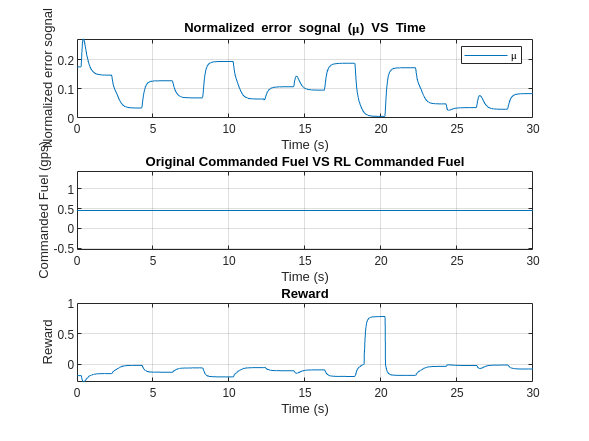

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
experiences = sim(env,agent,simOpts);
totalReward = sum(experiences.Reward);

% extract signals from simulation results
time = experiences.SimulationInfo.yout.time;
signals = experiences.SimulationInfo.yout.signals;
labels = {signals.label};

af = signals(contains(labels,'af')).values;
af_ref = signals(contains(labels,'ref')).values;
mu = signals(contains(labels,'mu')).values;
action_Fc = signals(contains(labels,'action_Fc')).values;
action_Fc = squeeze(action_Fc(1,1,:));
each_rewards = signals(contains(labels,'each_reward')).values;
each_rewards = squeeze(each_rewards(1,:,:))';
steady_reward = each_rewards(:,1);
edge_reward = each_rewards(:,2);
final_reward = sum(each_rewards,2);
reward = signals(contains(labels,'reward')).values;
reward = squeeze(reward(1,1,:))';


% plotting
figure(1);
subplot(3,1,1);
plot(time,mu);
title('Normalized error sognal (\mu) VS Time');
legend('\mu');
xlabel('Time (s)') ;
ylabel('Normalized error sognal') ;
grid on;
subplot(3,1,2);
plot(time(10:length(time)), action_Fc(10:length(action_Fc)));
title('Original Commanded Fuel VS RL Commanded Fuel');
xlabel('Time (s)') ;
ylabel('Commanded Fuel (gps)') ;
grid on;
subplot(3,1,3);
plot(time(10:length(time)), reward(10:length(reward)));
title('Reward');
xlabel('Time (s)') ;
ylabel('Reward') ;
grid on;

## Training progress info

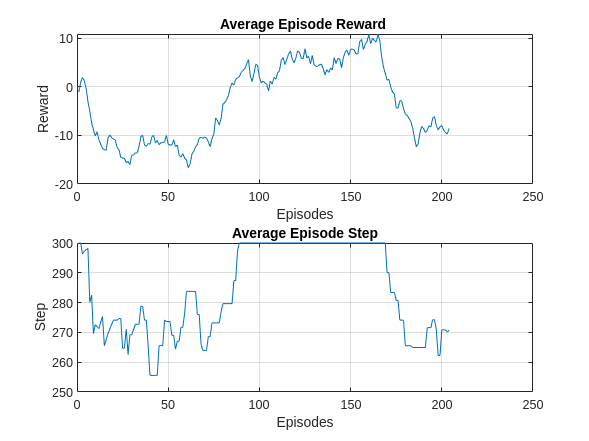

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(2);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on